%% Q2 – Design-Oriented Dynamics Analysis (15%)
% Building upon Q1 results to analyze system dynamics and propose specs
% -------------------------------------------------------------------------
clear; clc; close all;


%% LOAD Q1 RESULTS -------------------------------------------------------
% Load the identified models from Q1
if exist('IdentifiedModels.mat', 'file')
    load('IdentifiedModels.mat'); % Expects: mdlARX_A, mdlTF_A, mdlARX_B, mdlTF_B, mseTable, Ts, caseTags
    fprintf('Loaded Q1 results successfully.\n');
else
    error('Please run Q1 first to generate IdentifiedModels.mat and ensure all required variables are saved.');
end

Loaded Q1 results successfully.




%% SELECT BEST MODEL BASED ON Q1 RESULTS --------------------------------
% From Q1 analysis, select the model with the best generalization.
% Here, "best" is determined by the minimum one-step prediction MSE
% among the four models identified in Q1 (ARX/TFEST for Case A/B).

fprintf('\n=== MODEL SELECTION FROM Q1 ===\n');


=== MODEL SELECTION FROM Q1 ===


fprintf('MSE Table from Q1:\n');

MSE Table from Q1:


fprintf('              ARX           TFEST\n');

              ARX           TFEST


fprintf('%s   %10.4e   %10.4e\n', caseTags{1}, mseTable(1,:)); % Case A

Case A – Smooth Hovering   1.1376e-34   3.8255e-34


fprintf('%s   %10.4e   %10.4e\n', caseTags{2}, mseTable(2,:)); % Case B

Case B – Take-off + Drop   4.8657e-33   6.4369e-32



models = {mdlARX_A, mdlTF_A, mdlARX_B, mdlTF_B};
modelNames = {'ARX Case A', 'TFEST Case A', 'ARX Case B', 'TFEST Case B'};
mseValues = [mseTable(1,1), mseTable(1,2), mseTable(2,1), mseTable(2,2)];

[minMSE, bestIdx] = min(mseValues);
selectedModel = models{bestIdx};
selectedModelName = modelNames{bestIdx};

fprintf('Selected Model: %s (based on minimum MSE = %.4e)\n', selectedModelName, minMSE);

Selected Model: ARX Case A (based on minimum MSE = 1.1376e-34)



% Determine model type for display and specific processing
if contains(selectedModelName, 'ARX')
    modelType = 'ARX';
else
    modelType = 'TFEST';
end

% Display selected model details
fprintf('\n=== SELECTED MODEL DETAILS (''%s'') ===\n', selectedModelName);


=== SELECTED MODEL DETAILS ('ARX Case A') ===


disp(selectedModel);

  idpoly with properties:

                 A: [1 -1.4507 0 0.4579 -1.0030e-13]
                 B: [0 0.0012 0.0018 5.8376e-04]
                 C: 1
                 D: 1
                 F: 1
    IntegrateNoise: 0
          Variable: 'z^-1'
           IODelay: 0
         Structure: [1×1 pmodel.polynomial]
     NoiseVariance: 1.2038e-34
        InputDelay: 0
       OutputDelay: 0
         InputName: {'u1'}
         InputUnit: {''}
        InputGroup: [1×1 struct]
        OutputName: {'y1'}
        OutputUnit: {''}
       OutputGroup: [1×1 struct]
             Notes: [0×1 string]
          UserData: []
              Name: ''
                Ts: 0.0500
          TimeUnit: 'seconds'
      SamplingGrid: [1×1 struct]
            Report: [1×1 idresults.arx]



fprintf('Sampling Time (Ts): %.3f s\n', selectedModel.Ts);

Sampling Time (Ts): 0.050 s




%% PART (A): DERIVE TIME-DOMAIN RESPONSE ANALYTICALLY -------------------
fprintf('\n=== PART (A): ANALYTICAL TIME-DOMAIN RESPONSE CHARACTERIZATION ===\n');


=== PART (A): ANALYTICAL TIME-DOMAIN RESPONSE CHARACTERIZATION ===



fprintf('A full analytical derivation of the time-domain response y[k] would involve:\n');

A full analytical derivation of the time-domain response y[k] would involve:


fprintf('1. Defining a specific input, e.g., a unit step U(z) = z/(z-1).\n');

1. Defining a specific input, e.g., a unit step U(z) = z/(z-1).


fprintf('2. Computing the Z-transform of the output: Y(z) = G(z)U(z), where G(z) is the transfer function of the selected model.\n');

2. Computing the Z-transform of the output: Y(z) = G(z)U(z), where G(z) is the transfer function of the selected model.


fprintf('3. Performing partial fraction expansion of Y(z)/z.\n');

3. Performing partial fraction expansion of Y(z)/z.


fprintf('4. Applying the inverse Z-transform to each term to find the symbolic expression for y[k].\n');

4. Applying the inverse Z-transform to each term to find the symbolic expression for y[k].


fprintf('This process can be complex for higher-order systems and is beyond the scope of automated characterization in this script.\n');

This process can be complex for higher-order systems and is beyond the scope of automated characterization in this script.


fprintf('Instead, we will characterize the system''s dynamic properties using its poles, zeros, and numerical step response.\n\n');

Instead, we will characterize the system's dynamic properties using its poles, zeros, and numerical step response.




% Get poles and zeros
poles = pole(selectedModel);
zeros_val = zero(selectedModel); % Renamed to avoid conflict with zeros function

fprintf('System Poles (Discrete-time, z-plane):\n');

System Poles (Discrete-time, z-plane):


for i = 1:length(poles)
    if isreal(poles(i))
        fprintf('  p%d: %.4f\n', i, poles(i));
    else
        fprintf('  p%d: %.4f ± %.4fj (Mag: %.4f, Angle: %.2f°)\n', i, real(poles(i)), abs(imag(poles(i))), abs(poles(i)), rad2deg(angle(poles(i))));
    end
end

  p1: 0.9685 ± 0.0621j (Mag: 0.9704, Angle: 3.67°)
  p2: 0.9685 ± 0.0621j (Mag: 0.9704, Angle: -3.67°)


  p3: -0.4862
  p4: 0.0000



fprintf('System Zeros (Discrete-time, z-plane):\n');

System Zeros (Discrete-time, z-plane):


if isempty(zeros_val)
    fprintf('  No finite zeros.\n');
else
    for i = 1:length(zeros_val)
        if isreal(zeros_val(i))
            fprintf('  z%d: %.4f\n', i, zeros_val(i));
        else
            fprintf('  z%d: %.4f ± %.4fj (Mag: %.4f, Angle: %.2f°)\n', i, real(zeros_val(i)), abs(imag(zeros_val(i))), abs(zeros_val(i)), rad2deg(angle(zeros_val(i))));
        end
    end
end

  z1: 0.0000
  z2: -0.9802
  z3: -0.4862



% Attempt to convert to continuous-time for additional insight (optional)
polesCont = []; % Initialize
fprintf('\nAttempting continuous-time conversion (d2c) for pole analysis:\n');


Attempting continuous-time conversion (d2c) for pole analysis:


try
    sysc = d2c(selectedModel, 'zoh'); % Zero-Order Hold assumption
    polesCont = pole(sysc);
    fprintf('Equivalent Continuous-time Poles (s-plane):\n');
    for i = 1:length(polesCont)
        if isreal(polesCont(i))
            fprintf('  sc%d: %.4f\n', i, polesCont(i));
        else
            fprintf('  sc%d: %.4f ± %.4fj\n', i, real(polesCont(i)), abs(imag(polesCont(i))));
        end
    end
catch ME
    fprintf('  Could not convert to continuous-time: %s\n', ME.message);
    fprintf('  Proceeding with discrete-time analysis only for performance metrics.\n');
end

  Could not convert to continuous-time: The "zoh" and "foh" methods cannot be used for discrete models with poles near z=0.


  Proceeding with discrete-time analysis only for performance metrics.




%% PART (B): RELATE POLES TO SETTLING TIME AND OVERSHOOT ----------------
fprintf('\n=== PART (B): POLE-PERFORMANCE RELATIONSHIPS (Approximations) ===\n');


=== PART (B): POLE-PERFORMANCE RELATIONSHIPS (Approximations) ===



% Analyze dominant discrete-time poles (those closest to unit circle, excluding poles at origin)
valid_poles_for_dominance = poles(abs(poles) > 1e-3); % Ignore poles effectively at origin
if isempty(valid_poles_for_dominance)
    fprintf('No dominant poles found away from origin. System might be simple integrator or very fast.\n');
    % Initialize to avoid errors later if this path is taken
    dominant_pole = 0;zeta_equiv = NaN; omega_n_equivalent_continuous = NaN; actual_overshoot = NaN; actual_settling_time = NaN; steady_state = 0;
else
    [~, dominant_idx] = max(abs(valid_poles_for_dominance));
    dominant_pole = valid_poles_for_dominance(dominant_idx);

    fprintf('Most dominant discrete pole (largest magnitude away from origin): ');
    if isreal(dominant_pole)
        fprintf('%.6f', dominant_pole);
    else
        fprintf('%.6f ± %.6fj', real(dominant_pole), abs(imag(dominant_pole)));
    end
    fprintf(' (Magnitude: %.6f, Angle: %.2f°)\n', abs(dominant_pole), rad2deg(angle(dominant_pole)));

    % Estimate performance from dominant pole(s) - typically for underdamped 2nd order
    % These are approximations, treating the system as if dominated by a single pair of poles
    % and mapping them to equivalent continuous-time second-order system parameters.
    
    zeta_equiv = NaN; % Initialize
    omega_n_equivalent_continuous = NaN; % Initialize

    if ~isreal(dominant_pole)
        r_dom = abs(dominant_pole);
        theta_dom = angle(dominant_pole); % angle in radians

        if r_dom > 1e-6 && abs(theta_dom) > 1e-6 % Avoid issues with poles at origin or on real axis
            % Equivalent continuous-time damping ratio (zeta) and natural frequency (omega_n)
            % These formulas map discrete poles z = exp(s*Ts) back to s = -zeta*omega_n ± j*omega_n*sqrt(1-zeta^2)
            zeta_equiv = -log(r_dom) / sqrt(log(r_dom)^2 + theta_dom^2);
            omega_n_equivalent_continuous = sqrt(log(r_dom)^2 + theta_dom^2) / Ts;

            fprintf('\nApproximated from dominant complex pole pair:\n');
            fprintf('  Equivalent Damping Ratio (ζ_equiv): %.4f\n', zeta_equiv);
            fprintf('  Equivalent Natural Frequency (ω_n_equiv): %.4f rad/s\n', omega_n_equivalent_continuous);

            if zeta_equiv > 0 && zeta_equiv < 1
                est_overshoot = 100 * exp(-zeta_equiv * pi / sqrt(1 - zeta_equiv^2));
                est_settling_time_2pct = 4 / (zeta_equiv * omega_n_equivalent_continuous); % 2% settling time
                
                fprintf('  Estimated Overshoot (from ζ_equiv, ω_n_equiv): %.2f%%\n', est_overshoot);
                fprintf('  Estimated Settling Time (2%%, from ζ_equiv, ω_n_equiv): %.3f s\n', est_settling_time_2pct);
            elseif zeta_equiv >= 1
                fprintf('  System is estimated to be critically damped or overdamped (ζ_equiv ≥ 1).\n');
                fprintf('  No overshoot expected based on this approximation.\n');
                % For overdamped, settling time is related to the slower real part of the pole.
                % This approximation is simpler if we just use 4/(zeta*omega_n) which is for the envelope.
                 est_settling_time_2pct = 4 / (zeta_equiv * omega_n_equivalent_continuous);
                 fprintf('  Estimated Settling Time (2%%, from ζ_equiv, ω_n_equiv): %.3f s (envelope approx.)\n', est_settling_time_2pct);

            else
                 fprintf('  Estimated damping ratio is zero or negative - system might be unstable or marginally stable.\n');
            end
        else
            fprintf('  Dominant complex pole is on real axis or at origin, standard second-order approximations may not apply well.\n');
        end
    elseif isreal(dominant_pole) && abs(dominant_pole) < 1.0 % Stable real pole
        r_dom = abs(dominant_pole);
        if r_dom > 1e-6 % Avoid log(0)
            tau_discrete_equiv = -Ts / log(r_dom); % Equivalent time constant
            est_settling_time_2pct = 4 * tau_discrete_equiv; % For a first-order system

            fprintf('\nApproximated from dominant real pole:\n');
            fprintf('  Equivalent Time Constant (τ_equiv): %.3f s\n', tau_discrete_equiv);
            fprintf('  Estimated Settling Time (2%%, from τ_equiv): %.3f s\n', est_settling_time_2pct);
            fprintf('  No overshoot expected (real pole dominance).\n');
        else
             fprintf('  Dominant real pole very close to origin - implies very fast decay.\n');
        end
    else
        fprintf('  Dominant pole is unstable or analysis is inconclusive based on single dominant pole.\n');
    end
end

Most dominant discrete pole (largest magnitude away from origin): 

0.968457 ± 0.062096j

 (Magnitude: 0.970446, Angle: 3.67°)



Approximated from dominant complex pole pair:


  Equivalent Damping Ratio (ζ_equiv): 0.4243


  Equivalent Natural Frequency (ω_n_equiv): 1.4142 rad/s


  Estimated Overshoot (from ζ_equiv, ω_n_equiv): 22.95%


  Estimated Settling Time (2%, from ζ_equiv, ω_n_equiv): 6.667 s



%% STEP RESPONSE ANALYSIS (Numerical Verification) ------------------------
fprintf('\n=== NUMERICAL STEP RESPONSE VERIFICATION ===\n');


=== NUMERICAL STEP RESPONSE VERIFICATION ===



% Generate step response
simulation_time = 10; % seconds, adjust as needed
time_vector = 0:Ts:simulation_time;
[y_step, t_step] = step(selectedModel, time_vector);


% *** NEW: Display first few points of the direct step response ***
fprintf('\nDirect Step Response Data (First 20 points or fewer):\n');


Direct Step Response Data (First 20 points or fewer):


fprintf('   Time (s)    Output y[k]\n');

   Time (s)    Output y[k]


fprintf('   --------    -----------\n');

   --------    -----------


num_points_to_display = min(20, length(t_step));
for i = 1:num_points_to_display
    fprintf('   %.4f      %.6f\n', t_step(i), y_step(i));
end

   0.0000      0.000000
   0.0500      0.001225
   0.1000      0.004798
   0.1500      0.010565
   0.2000      0.018371
   0.2500      0.028058
   0.3000      0.039470
   0.3500      0.052452
   0.4000      0.066849
   0.4500      0.082509
   0.5000      0.099282
   0.5500      0.117022
   0.6000      0.135587
   0.6500      0.154838
   0.7000      0.174643
   0.7500      0.194872
   0.8000      0.215404
   0.8500      0.236121
   0.9000      0.256911
   0.9500      0.277669


fprintf('\n');
% *** END NEW SECTION ***

if isempty(y_step)
    fprintf('Could not generate step response. The model might be improper or unstable.\n');
    actual_overshoot = NaN; actual_settling_time = NaN; steady_state = NaN; peak_val = NaN; peak_idx = 1;
else
    % Find actual performance metrics
    if abs(y_step(end)) < 1e-9 % Effectively zero steady state
        steady_state = 0;
    else
        steady_state = y_step(end);
    end
    
    fprintf('Numerical Step Response Metrics:\n');
    fprintf('  Steady-state value: %.6f\n', steady_state);

    if abs(steady_state) > 1e-6 % Avoid division by zero if steady state is effectively zero
        [peak_val, peak_idx] = max(y_step);
        actual_overshoot = (peak_val - steady_state) / steady_state * 100;
        actual_overshoot = max(0, actual_overshoot); % Overshoot cannot be negative
        fprintf('  Peak value: %.6f at t=%.2fs\n', peak_val, t_step(peak_idx));
        fprintf('  Actual Overshoot: %.2f%%\n', actual_overshoot);
    else
        fprintf('  Steady-state value is near zero. Overshoot calculation is not meaningful or system does not settle to a non-zero value.\n');
        actual_overshoot = 0; % Or NaN, depending on desired interpretation
        peak_val = max(y_step); 
        peak_idx = find(y_step == peak_val, 1);
        if isempty(peak_idx) && ~isempty(peak_val) % handle case where peak_val might be empty
            peak_idx = 1;
        elseif isempty(peak_idx) && isempty(peak_val)
             peak_idx = 1; peak_val = NaN; % Safety
        end
        fprintf('  Peak value: %.6f at t=%.2fs\n', peak_val, t_step(peak_idx));
    end

    % Find settling time (e.g., 2% criterion)
    settling_band_pct = 0.02;
    settling_band_abs_val = settling_band_pct * abs(steady_state);
    
    % If steady_state is very small, use a small absolute band instead
    if abs(steady_state) < 1e-3 
        settling_band_abs_val = 1e-3; % Use a small absolute tolerance
        fprintf('  Using absolute settling band of %.1e due to small steady-state value.\n', settling_band_abs_val);
    end

    % Find last point outside settling band
    indices_outside_band = find(abs(y_step - steady_state) > settling_band_abs_val);
    if ~isempty(indices_outside_band)
        last_outside_idx = indices_outside_band(end);
        % Ensure we don't go out of bounds if system never settles
        if last_outside_idx < length(t_step)
            actual_settling_time = t_step(last_outside_idx + 1);
        else % System did not settle within simulation time
            actual_settling_time = inf; 
        end
    else % Settled immediately or before first sample (within tolerance)
        actual_settling_time = t_step(1); % Or 0, depends on interpretation
    end
    
    if isinf(actual_settling_time)
        fprintf('  Actual Settling Time (to ±%.0f%% of SS or ±%.1e abs): Did not settle within %.1f s.\n', settling_band_pct*100, settling_band_abs_val, simulation_time);
    else
        fprintf('  Actual Settling Time (to ±%.0f%% of SS or ±%.1e abs): %.3f s\n', settling_band_pct*100, settling_band_abs_val, actual_settling_time);
    end
end

Numerical Step Response Metrics:


  Steady-state value: 0.498658


  Peak value: 0.614743 at t=2.45s


  Actual Overshoot: 23.28%


  Actual Settling Time (to ±2% of SS or ±1.0e-02 abs): 5.900 s



%% PART (C): PROPOSE PERFORMANCE SPECIFICATION TABLE --------------------
fprintf('\n=== PART (C): PERFORMANCE SPECIFICATION TABLE ===\n');


=== PART (C): PERFORMANCE SPECIFICATION TABLE ===


% These are example specifications and should be tailored to the specific UAV application.
fprintf('PERFORMANCE SPECIFICATIONS FOR UAV VERTICAL CONTROL (Example):\n');

PERFORMANCE SPECIFICATIONS FOR UAV VERTICAL CONTROL (Example):


fprintf('%-22s %-15s %-15s %-15s\n', 'Metric', 'Strict', 'Moderate', 'Relaxed');

Metric                 Strict          Moderate        Relaxed        


fprintf('%-22s %-15s %-15s %-15s\n', repmat('-',1,22), repmat('-',1,15), repmat('-',1,15), repmat('-',1,15));

---------------------- --------------- --------------- ---------------


fprintf('%-22s %-15s %-15s %-15s\n', 'Settling Time (2%)', '< 0.8 s', '< 1.5 s', '< 3.0 s');

Settling Time (2%)     < 0.8 s         < 1.5 s         < 3.0 s        


fprintf('%-22s %-15s %-15s %-15s\n', 'Overshoot', '< 2%', '< 5%', '< 10%');

Overshoot              < 2%            < 5%            < 10%          


fprintf('%-22s %-15s %-15s %-15s\n', 'Steady-State Error', '< 1%', '< 2%', '< 5%'); % To a step input

Steady-State Error     < 1%            < 2%            < 5%           


fprintf('%-22s %-15s %-15s %-15s\n', 'Rise Time (10-90%)', '< 0.3 s', '< 0.6 s', '< 1.2 s');

Rise Time (10-90%)     < 0.3 s         < 0.6 s         < 1.2 s        


fprintf('%-22s %-15s %-15s %-15s\n', 'Gain Margin', '> 10 dB', '> 6 dB', '> 3 dB');

Gain Margin            > 10 dB         > 6 dB          > 3 dB         


fprintf('%-22s %-15s %-15s %-15s\n', 'Phase Margin', '> 60 deg', '> 45 deg', '> 30 deg');

Phase Margin           > 60 deg        > 45 deg        > 30 deg       




%% CURRENT SYSTEM ASSESSMENT AGAINST PROPOSED SPECS (using Moderate as baseline)
fprintf('\n=== CURRENT SYSTEM ASSESSMENT (vs. Moderate Specs) ===\n');


=== CURRENT SYSTEM ASSESSMENT (vs. Moderate Specs) ===


if isnan(actual_settling_time) || isnan(actual_overshoot)
    fprintf('Cannot assess system as step response metrics are NaN.\n');
else
    % Settling time assessment
    if isinf(actual_settling_time)
        fprintf('Settling Time: Does not settle. (Moderate spec: < 1.5 s) - FAIL\n');
    elseif actual_settling_time < 1.5
        fprintf('Settling Time: %.3f s (Moderate spec: < 1.5 s) - PASS\n', actual_settling_time);
    else
        fprintf('Settling Time: %.3f s (Moderate spec: < 1.5 s) - FAIL\n', actual_settling_time);
    end

    % Overshoot assessment
    if actual_overshoot < 5
        fprintf('Overshoot: %.2f%% (Moderate spec: < 5%%) - PASS\n', actual_overshoot);
    else
        fprintf('Overshoot: %.2f%% (Moderate spec: < 5%%) - FAIL\n', actual_overshoot);
    end
    
    % Stability margins (if computable)
    try
        [Gm, Pm, Wcg, Wcp] = margin(selectedModel);
        if isinf(Gm) % Inf Gm often means stable
             fprintf('Gain Margin: Inf dB (Stable) (Moderate spec: > 6 dB) - PASS\n');
        else
             fprintf('Gain Margin: %.2f dB (Moderate spec: > 6 dB) - %s\n', 20*log10(Gm), ternary(20*log10(Gm)>6, 'PASS', 'FAIL'));
        end
        fprintf('Phase Margin: %.2f deg (Moderate spec: > 45 deg) - %s\n', Pm, ternary(Pm>45, 'PASS', 'FAIL'));
    catch ME_margin
        fprintf('Could not compute stability margins: %s\n', ME_margin.message);
        Gm = NaN; Pm = NaN; % Set to NaN if not computable
    end
end

Settling Time: 5.900 s (Moderate spec: < 1.5 s) - FAIL


Overshoot: 23.28% (Moderate spec: < 5%) - FAIL


Gain Margin: 33.72 dB (Moderate spec: > 6 dB) - PASS


Phase Margin: Inf deg (Moderate spec: > 45 deg) - PASS


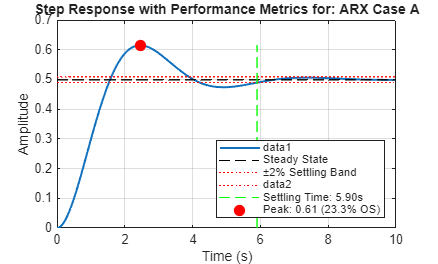


%% GENERATE PLOTS FOR DELIVERABLES ---------------------------------------
% Plot 1: Step response with performance metrics
figure('Name', [selectedModelName ' | Step Response Analysis']);
if ~isempty(y_step)
    plot(t_step, y_step, 'LineWidth', 1.5);
    hold on;
    grid on;
    
    % Add steady-state line
    line([t_step(1), t_step(end)], [steady_state, steady_state], 'Color', 'k', 'LineStyle', '--', 'DisplayName', 'Steady State');

    % Add settling time bands and line
    if ~isinf(actual_settling_time) && actual_settling_time <= t_step(end) && ~isnan(steady_state)
        upper_band = steady_state * (1 + settling_band_pct);
        lower_band = steady_state * (1 - settling_band_pct);
        if abs(steady_state) < 1e-3 % Adjust for absolute band if used
            upper_band = steady_state + settling_band_abs_val;
            lower_band = steady_state - settling_band_abs_val;
        end
        line([t_step(1), t_step(end)], [upper_band, upper_band], 'Color', 'r', 'LineStyle', ':', 'DisplayName', sprintf('±%.0f%% Settling Band',settling_band_pct*100));
        line([t_step(1), t_step(end)], [lower_band, lower_band], 'Color', 'r', 'LineStyle', ':');
        line([actual_settling_time, actual_settling_time], [min(y_step(isfinite(y_step))), max(y_step(isfinite(y_step)))], 'Color', 'g', 'LineStyle', '--', 'DisplayName', sprintf('Settling Time: %.2fs', actual_settling_time));
    end

    % Add overshoot marker
    if actual_overshoot > 0 && ~isnan(peak_val) && peak_idx <= length(t_step) && t_step(peak_idx) <= simulation_time
        plot(t_step(peak_idx), peak_val, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r', 'DisplayName', sprintf('Peak: %.2f (%.1f%% OS)', peak_val, actual_overshoot));
    end
    
    title(['Step Response with Performance Metrics for: ', selectedModelName]);
    xlabel('Time (s)');
    ylabel('Amplitude');
    legend('show', 'Location', 'SouthEast');
    hold off;
else
    disp('Skipping step response plot as y_step is empty.');
end

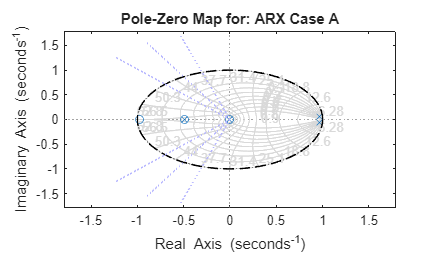



% Plot 2: Pole-zero map with stability regions
figure('Name', [selectedModelName ' | Pole-Zero Map']);
pzmap(selectedModel);
hold on;

% Add unit circle for discrete-time stability
theta_uc = 0:0.01:2*pi;
plot(cos(theta_uc), sin(theta_uc), 'k--', 'LineWidth', 1.2, 'DisplayName', 'Unit Circle');
grid on;
axis equal;
% Try to set reasonable limits, but pzmap might override
current_xlim = xlim; current_ylim = ylim;
max_abs_lim = max([abs(current_xlim), abs(current_ylim), 1.2]);
xlim([-max_abs_lim, max_abs_lim]);
ylim([-max_abs_lim, max_abs_lim]);

% Add simplified damping ratio lines (lines of constant angle from origin)
% These are visual aids and not exact logarithmic spirals of constant zeta.
% The angle relates to zeta for poles ON the unit circle, or for the imaginary part vs real part ratio.
zeta_lines_vis = [0.3, 0.5, 0.7]; % Example zeta values for visualization
if any(~isreal(poles)) % Only if complex poles exist
    for zeta_vis = zeta_lines_vis
        % For z = r*exp(j*theta), if mapped from s = sigma + j*omega_d
        % For constant zeta, theta_s = acos(zeta) is angle from negative real axis in s-plane
        % This is a simplification for visualization.
        angle_from_real_axis_approx = acos(zeta_vis); % angle with negative real axis in s-plane
                                               % becomes more complex in z-plane for lines
        % Plot lines at angles corresponding to where dominant oscillations might occur
        % This is a very rough visual guide
        phi_vis_pos = pi - angle_from_real_axis_approx; % Angle for upper half plane
        % phi_vis_neg = pi + angle_from_real_axis_approx; % Angle for lower half plane (or -phi_vis_pos) % Redundant due to symmetry
        
        line([0, max_abs_lim*cos(phi_vis_pos)], [0, max_abs_lim*sin(phi_vis_pos)], 'Color', [0.7 0.7 1], 'LineStyle', ':', 'HandleVisibility','off');
        line([0, max_abs_lim*cos(-phi_vis_pos)], [0, max_abs_lim*sin(-phi_vis_pos)], 'Color', [0.7 0.7 1], 'LineStyle', ':', 'HandleVisibility','off');
        % text(0.8*cos(phi_vis_pos), 0.8*sin(phi_vis_pos), sprintf('\\zeta ~ %.1f',zeta_vis), 'Color', [0.5 0.5 1]);
    end
    text(0.1*max_abs_lim, -0.9*max_abs_lim,' Simplified lines related to damping regions.', 'VerticalAlignment','bottom', 'HorizontalAlignment','center', 'Color', [0.5 0.5 1], 'FontSize', 7);
end

title(['Pole-Zero Map for: ', selectedModelName]);
legend('show','Location','NorthEastOutside');
hold off;



%% MATH-TO-INTUITION EXPLANATION ----------------------------------------
fprintf('\n=== MATH-TO-INTUITION EXPLANATION ===\n');


=== MATH-TO-INTUITION EXPLANATION ===


fprintf('The dynamic behavior of the UAV''s vertical motion, as represented by the model "%s",\n', selectedModelName);

The dynamic behavior of the UAV's vertical motion, as represented by the model "ARX Case A",


fprintf('is primarily governed by the locations of its poles and zeros in the z-plane:\n\n');

is primarily governed by the locations of its poles and zeros in the z-plane:




fprintf('1. POLES (Roots of the denominator of the transfer function):\n');

1. POLES (Roots of the denominator of the transfer function):


fprintf('   - Stability: For the system to be stable, all poles MUST lie INSIDE the unit circle (magnitude < 1).\n');

   - Stability: For the system to be stable, all poles MUST lie INSIDE the unit circle (magnitude < 1).


fprintf('     Poles on or outside the unit circle lead to responses that are oscillatory without decay, or grow unbounded.\n');

     Poles on or outside the unit circle lead to responses that are oscillatory without decay, or grow unbounded.


fprintf('   - Speed of Response & Decay Rate:\n');

   - Speed of Response & Decay Rate:


fprintf('     > Poles closer to the origin (smaller magnitude) correspond to faster-decaying response components.\n');

     > Poles closer to the origin (smaller magnitude) correspond to faster-decaying response components.


fprintf('     > Poles closer to the unit circle (larger magnitude, but < 1) correspond to slower-decaying components.\n');

     > Poles closer to the unit circle (larger magnitude, but < 1) correspond to slower-decaying components.


fprintf('       These "dominant poles" often dictate the overall settling time.\n');

       These "dominant poles" often dictate the overall settling time.


fprintf('   - Nature of Response (Oscillatory vs. Non-oscillatory):\n');

   - Nature of Response (Oscillatory vs. Non-oscillatory):


fprintf('     > Real Poles: Contribute exponential terms to the response (e.g., A * (pole_value)^k).\n');

     > Real Poles: Contribute exponential terms to the response (e.g., A * (pole_value)^k).


fprintf('     > Complex Conjugate Poles (a ± bj): Contribute damped oscillatory terms (e.g., A * (magnitude)^k * cos(angle*k + phase)).\n');

     > Complex Conjugate Poles (a ± bj): Contribute damped oscillatory terms (e.g., A * (magnitude)^k * cos(angle*k + phase)).


fprintf('       The angle of the complex pole relates to the frequency of oscillation.\n');

       The angle of the complex pole relates to the frequency of oscillation.


fprintf('       The magnitude relates to the decay rate of these oscillations.\n');

       The magnitude relates to the decay rate of these oscillations.



if exist('zeta_equiv', 'var') && ~isnan(zeta_equiv) && ~isreal(dominant_pole)
    fprintf('   - Damping (for complex poles): The equivalent continuous-time damping ratio (ζ_equiv ~ %.3f estimated for the dominant complex pole)\n', zeta_equiv);
    fprintf('     indicates how oscillatory the response is. Lower ζ means more overshoot and oscillation.\n');
end

   - Damping (for complex poles): The equivalent continuous-time damping ratio (ζ_equiv ~ 0.424 estimated for the dominant complex pole)


     indicates how oscillatory the response is. Lower ζ means more overshoot and oscillation.


if exist('dominant_pole','var') % ensure dominant_pole exists before printing
    fprintf('     Our dominant pole is at z = ');
    if isreal(dominant_pole)
        fprintf('%.4f', dominant_pole);
    else
        fprintf('%.4f ± %.4fj (Mag: %.4f)', real(dominant_pole), abs(imag(dominant_pole)), abs(dominant_pole));
    end
    fprintf('. Its location suggests characteristics seen in the step response.\n\n');
else
    fprintf('\n');
end

     Our dominant pole is at z = 

0.9685 ± 0.0621j (Mag: 0.9704)

. Its location suggests characteristics seen in the step response.





fprintf('2. ZEROS (Roots of the numerator of the transfer function):\n');

2. ZEROS (Roots of the numerator of the transfer function):


fprintf('   - Zeros affect the amplitude and shape of the response components determined by the poles.\n');

   - Zeros affect the amplitude and shape of the response components determined by the poles.


fprintf('   - They do NOT determine stability directly but can introduce phenomena like initial undershoot (for non-minimum phase zeros, i.e., zeros outside the unit circle).\n');

   - They do NOT determine stability directly but can introduce phenomena like initial undershoot (for non-minimum phase zeros, i.e., zeros outside the unit circle).


fprintf('   - Zeros can also "cancel out" or reduce the effect of a nearby pole if they are close to each other.\n\n');

   - Zeros can also "cancel out" or reduce the effect of a nearby pole if they are close to each other.




fprintf('3. RELATION TO UAV PERFORMANCE (e.g., for "%s"):\n', selectedModelName);

3. RELATION TO UAV PERFORMANCE (e.g., for "ARX Case A"):


if exist('actual_settling_time','var') && exist('actual_overshoot','var') && ~isnan(actual_settling_time) && ~isnan(actual_overshoot)
    fprintf('   - Settling Time: Largely influenced by the magnitude of the dominant pole(s). To achieve a fast settling time (e.g., %.2f s observed),\n', actual_settling_time);
    fprintf('     dominant poles should be well within the unit circle, but not too close to the origin if excessive speed is not needed.\n');
    fprintf('   - Overshoot: Primarily related to complex poles and their effective damping. Low overshoot (e.g., %.2f%% observed) implies good damping (ζ not too small).\n', actual_overshoot);
else
     fprintf('   - Settling Time and Overshoot metrics were not available for direct comparison here.\n');
end

   - Settling Time: Largely influenced by the magnitude of the dominant pole(s). To achieve a fast settling time (e.g., 5.90 s observed),


     dominant poles should be well within the unit circle, but not too close to the origin if excessive speed is not needed.


   - Overshoot: Primarily related to complex poles and their effective damping. Low overshoot (e.g., 23.28% observed) implies good damping (ζ not too small).


fprintf('     Zeros can also significantly influence overshoot.\n');

     Zeros can also significantly influence overshoot.


fprintf('   - Design Trade-offs: Moving poles to achieve faster response (further from unit circle, towards origin) can sometimes reduce stability margins or increase sensitivity.\n');

   - Design Trade-offs: Moving poles to achieve faster response (further from unit circle, towards origin) can sometimes reduce stability margins or increase sensitivity.


fprintf('     Controller design aims to place the closed-loop poles in desired locations to meet performance specs like those proposed (e.g., strict: Ts < 0.8s, OS < 2%%).\n');

     Controller design aims to place the closed-loop poles in desired locations to meet performance specs like those proposed (e.g., strict: Ts < 0.8s, OS < 2%).



%% SAVE RESULTS FOR NEXT QUESTIONS ---------------------------------------
% Ensure Gm and Pm are defined, even if NaN
if ~exist('Gm', 'var') || isempty(Gm), Gm = NaN; end
if ~exist('Pm', 'var') || isempty(Pm), Pm = NaN; end
if ~exist('actual_settling_time','var'), actual_settling_time = NaN; end
if ~exist('actual_overshoot','var'), actual_overshoot = NaN; end
if ~exist('steady_state','var'), steady_state = NaN; end


save('Q2_DynamicsAnalysis.mat', 'selectedModel', 'selectedModelName', 'modelType', ...
     'actual_settling_time', 'actual_overshoot', 'steady_state', 'Gm', 'Pm', ...
     'poles', 'zeros_val', 'Ts'); % Added Ts for consistency

fprintf('\n=== Q2 ANALYSIS COMPLETE ===\n');


=== Q2 ANALYSIS COMPLETE ===


fprintf('Results saved to Q2_DynamicsAnalysis.mat for use in Q3-Q5\n');

Results saved to Q2_DynamicsAnalysis.mat for use in Q3-Q5



% ----- small ternary helper (if not available in older MATLAB) -----
function out = ternary(cond,a,b)
    if cond
        out = a;
    else
        out = b;
    end
end